clear variables;

Fs      = 8500;
T       = 1 / Fs;
L       = Fs * 2;
t       = (0:L-1) * T;

s1 = 2 * sin(2 * pi * 10 * t);
s2 = 5 * sin(2 * pi * 100 * t);
s3 = 10 * sin(2 * pi * 200 * t);
noise = 2 * randn(size(t));

sSum = s1 + s2 + s3;
withNoise = sSum + noise;

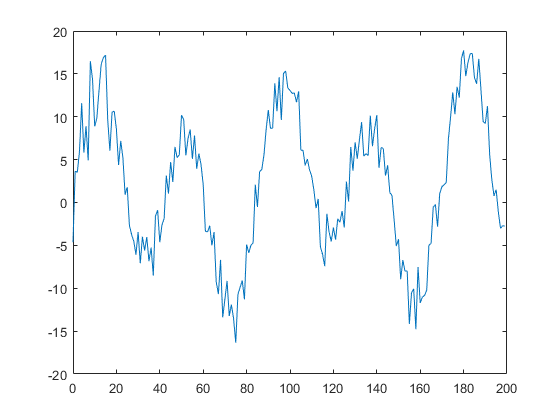

soundsc(withNoise, Fs);

plot(Fs * t(1:200), withNoise(1:200));

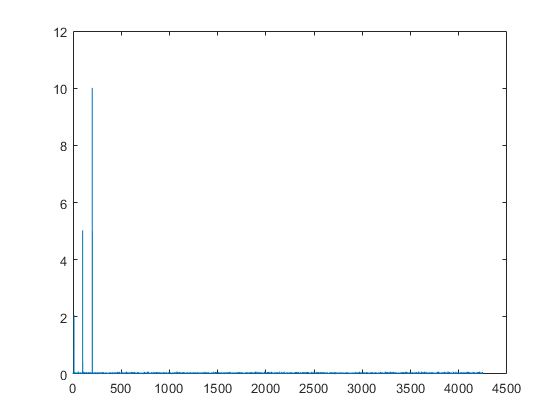

Y = fft(withNoise);

P2 = abs(Y / L);
P1 = P2(1:L / 2 + 1);
P1(2:end-1) = 2 * P1(2:end-1);
f = Fs*(0:(L/2)) / L;
plot(f, P1);

Zadanie 10. Spektrogram

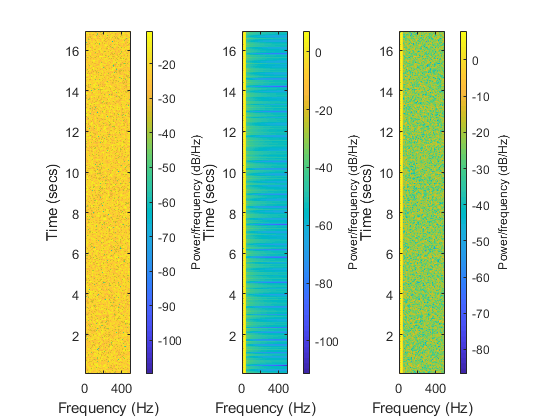

figure(1);
subplot(1, 3, 1);
spectrogram(noise, 128, 120, 128, 1e3);

subplot(1, 3, 2);
spectrogram(sSum, 128, 120, 128, 1e3);

subplot(1, 3, 3);
spectrogram(withNoise, 128, 120, 128, 1e3);